cooperation frequency as a function of L and alpha, L and w

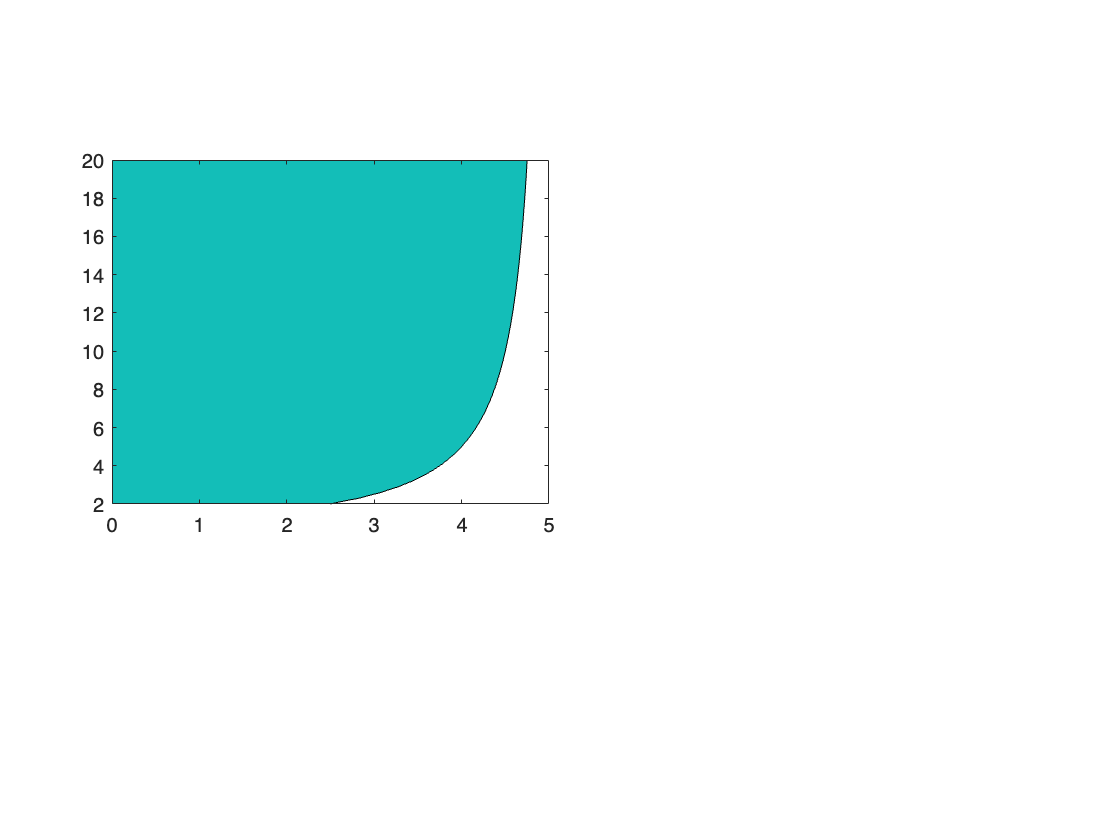

color_list = [102 102 255;
              255 102 102;
              0 156 0;
              102 102 0;
              153 0 0;
              0 0 196;
              0 0 0;
              156 156 156;
              0 153 153;
              0 128 255;
              255 255 255]/255;
linewidth1 = 1.0;
linewidth2 = 0.6;
marksize = 8;
fontsize_scale = 12;
fontsize_variable = 12;

syms delta lambda alpha b c L w;
xlinear = 1/2+(L+1)/(12*L)*((b-c)*lambda-lambda*alpha*L/(L-1));
t = (L*(1-w)-(1-w^L))/((1-w)*(1-w^(L-1)));
xnonlinear = 1/2+(L+1)/(12*L)*((2*t*b/L-c)*lambda-lambda*alpha*L/(L-1));

figure(1);
subplot(1,2,1)
pos = [0.10 0.40 0.39 0.41];
ax = subplot('Position',pos);

L_list = 2:0.3:20;
alpha_list = 5*(0:0.01:1);
xC_mat1 = zeros(length(alpha_list),length(L_list));
for i = 1:length(alpha_list)
    for j = 1:length(L_list)
        xC_mat1(i,j) = subs(xlinear,[lambda alpha b c L],[0.1 alpha_list(i) 6 1 L_list(j)]);
    end
end
[X1,Y1] = meshgrid(alpha_list,L_list);
[cb,~] = contourf(X1,Y1,transpose(xC_mat1),[0.5 0.5]);

[~,h] = contourf(X1,Y1,transpose(xC_mat1),0.44:0.11/33:0.55); hold on;
colormap(parula);
set(h,'LineColor','none');
colorbar();
plot(cb(1,2:cb(2,1)+1),cb(2,2:cb(2,1)+1),'--','LineWidth',linewidth1,'Color',color_list(7,:)); hold on;
cb1 = cb;

list = find(alpha_list<2.5);
L_list1 = zeros(length(list),1);
for i = 1:length(list)
    L_list1(i) = 1/(1-sqrt(2*alpha_list(i)/5));
end
plot(alpha_list(list),L_list1(list),'-','LineWidth',linewidth1,'Color',color_list(7,:)); hold on;

xlim = [0,5];
ylim = [2,20];
set(ax,'Fontname','Arial','FontSize',fontsize_variable,'linewidth',linewidth2);
set(ax,'xlim',xlim);
set(ax,'XTick',0:1:5);
set(ax,'ylim',ylim);
set(ax,'YTick',2:3:20);

xlabel('Need threshold, $$\alpha$$','interpreter','latex','FontSize',fontsize_variable,'Fontname', 'Arial');
ylabel('Number of levels, $$L$$','interpreter','latex','FontSize',fontsize_variable,'Fontname', 'Arial');
text(ax,-0.18,1.08,'a','Units','Normalized','FontName','Arial','FontWeight','bold','FontSize',fontsize_variable);

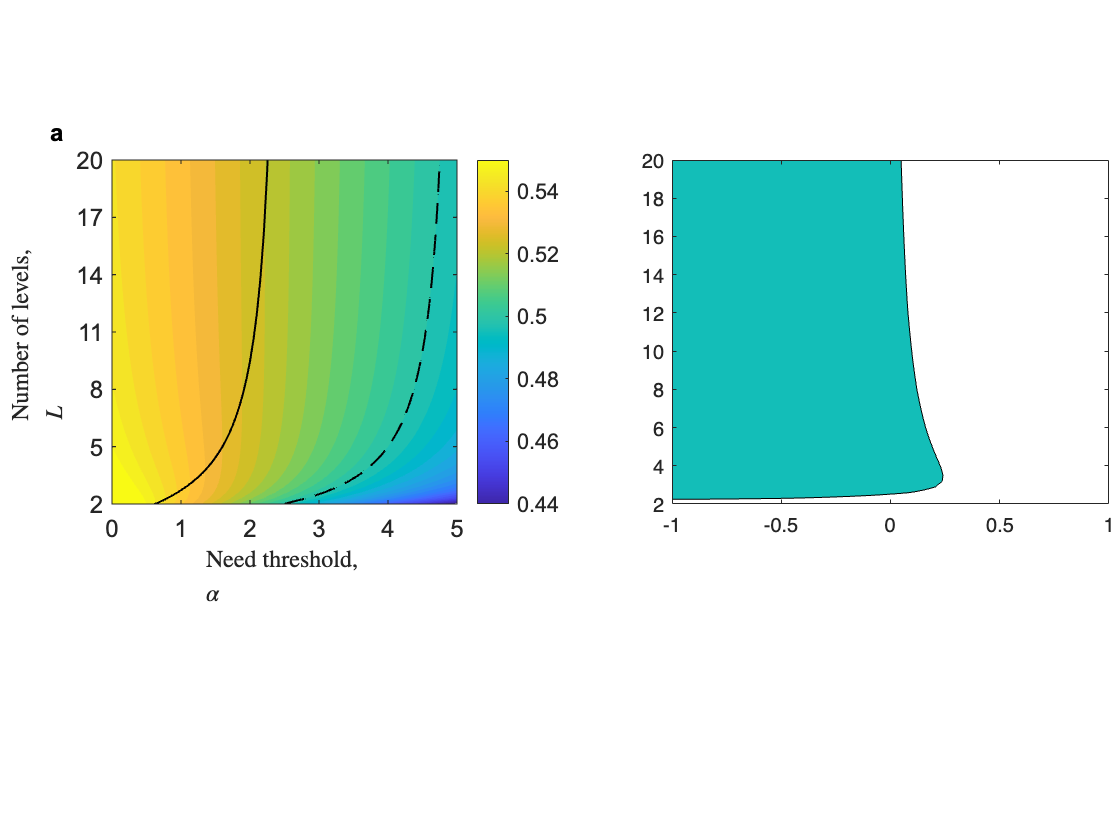

subplot(1,2,2)
pos = [0.60 0.40 0.39 0.41];
ax = subplot('Position',pos);

alpha_bc = 0.6;
L_list = 2:0.3:20;
w_list = -1:0.04:1;
xC_mat = zeros(length(w_list),length(L_list));
for i = 1:length(w_list)
    for j = 1:length(L_list)
        if w_list(i) ~= 0
        xC_mat(i,j) = subs(xnonlinear,[lambda alpha b c L w],[0.1 alpha_bc*5 6 1 L_list(j) 10^w_list(i)]);
        else 
            xC_mat(i,j) = subs(xlinear,[lambda alpha b c L],[0.1 alpha_bc*5 6 1 L_list(j)]);
        end
    end
end
[X,Y] = meshgrid(w_list,L_list);
[cb,~] = contourf(X,Y,transpose(xC_mat),[0.5 0.5]);

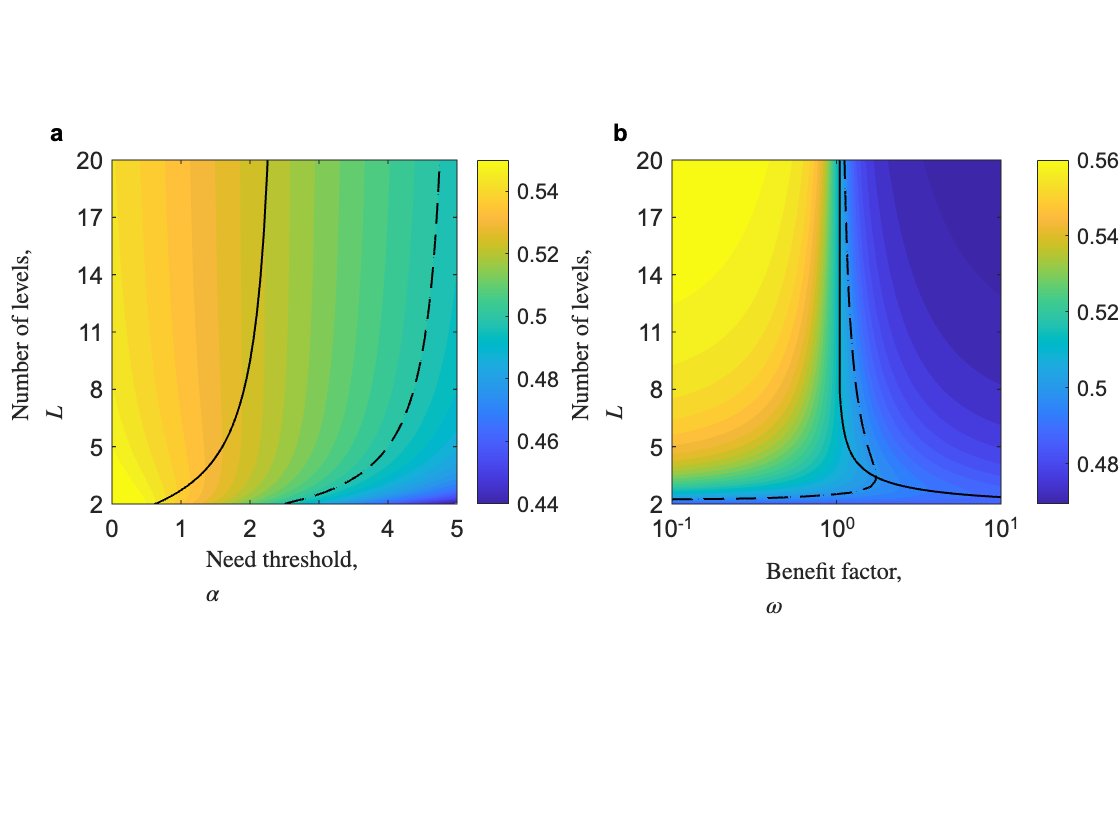

cb2 = cb;
[~,h] = contourf(X,Y,transpose(xC_mat),0.46:0.1/36:0.56); hold on;
set(h,'LineColor','none');
colormap(parula);
colorbar();
plot(cb(1,2:cb(2,1)+1),cb(2,2:cb(2,1)+1),'--','LineWidth',linewidth1,'Color',color_list(7,:)); hold on;

w_list = [0:0.005:0.1 0.12:0.04:1];
L_list2 = zeros(length(w_list),1);
for i = 1:length(w_list)
    xC_L = subs(xlinear,[lambda alpha b c],[0.1 alpha_bc*5 6 1]);
    if w_list(i) ~= 0
        xC_L = subs(xnonlinear,[lambda alpha b c w],[0.1 alpha_bc*5 6 1 10^w_list(i)]);
    end
    yy = simplify(diff(xC_L, L));

    func = matlabFunction(yy,'Vars',L);
    options = optimset('Display','off');
    solution = fzero(func, 5, options);
    L_list2(i) = solution;
end
plot([w_list(5),w_list(5:end)],[20,transpose(L_list2(5:end))],'-','LineWidth',linewidth1,'Color',color_list(7,:)); hold on;

xlim = [-1,1];
ylim = [2,20];
set(ax,'Fontname','Arial','FontSize',fontsize_variable,'linewidth',linewidth2);
set(ax,'xlim',xlim);
set(ax,'XTick',-1:1:1);
xtickformat('%.1f');
set(gca,'XTickLabel',{'10^{-1}','10^0','10^1'},'FontSize',fontsize_variable,'Fontname', 'Arial');
set(ax,'ylim',ylim);
set(ax,'YTick',2:3:20);

xlabel('Benefit factor, $$\omega$$','interpreter','latex','FontSize',fontsize_variable,'Fontname', 'Arial');
ylabel('Number of levels, $$L$$','interpreter','latex','FontSize',fontsize_variable,'Fontname', 'Arial');
text(ax,-0.18,1.08,'b','Units','Normalized','FontName','Arial','FontWeight','bold','FontSize',fontsize_variable);

print('-dpdf','Figure4.pdf');